clc;
clear values

## PARTIE I

## QUESTION 1


A = [-1 4 0; 2 0 1; 2 6 2];
B = [2 1 5; 4 0 9; -1 3 6];
C = ones(2,2);

A*B

ans =     14    -1    31
     3     5    16
    26     8    76


A.*B

ans =     -2     4     0
     8     0     9
    -2    18    12


A.^2

ans =      1    16     0
     4     0     1
     4    36     4


A>1

ans = 3×3 logical array
   0   1   0
   1   0   0
   1   1   1


A(A>1)=0

A =     -1     0     0
     0     0     1
     0     0     0


## QUESTION 2

[y] = func1(5.7)

'func1' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\emman\Desktop\2021-2022 Dauphine\2021-2022 272 Dauphine IEF\Econometrie non lineaire\TP1

Change the MATLAB current folder or add its folder to the MATLAB path.

## QUESTION 3

gen = zeros(1000,1);
for c = 2:1000
   gen(c,1) = gen(c-1,1) + randn;
end

figure(1);
subplot(1,1,1); plot(gen)

%%version while
c = 2;
while c <= 1000
   gen(c,1) = gen(c-1,1) + randn;
   c = c+1;
end

figure(2);
plot(gen)

figure(3);
e = randn(1000,252);
gen2 = cumsum(e);
plot (gen2)

## QUESTION 4

x = linspace(0,pi,30);

figure(4);
subplot(1,3,1);
plot(cos(x));
subplot(1,3,2);
plot(sin(x));
subplot(1,3,3);
plot(exp(x));

## QUESTION 5

x0=randn(2,1);
options=optimset('MaxIter', 1000, 'TolFun', 10^-10, 'TolX', 10^-10);
[x_opt, fval, code, info, grad, H]=fminunc(@rosenbrock, x0, options)

## PARTIE II

## EXERCICE I - Simulation AR(1)

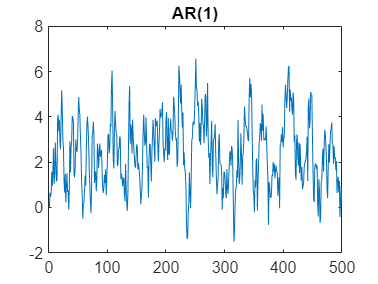

clear memoire;
clc;
clear values;

c=0.5;
phi=0.8;
sigma=0.9;
T=500;

rng(100) % pour avoir tous le même graph % random number generation (rng)

x = zeros(T,1); % vecteur zeros(l,c)

for t = 2:T
   x(t,1) = c + phi*x(t-1,1) + sigma*randn;
end

figure(5);
plot(x);
title("AR(1)")

## EXERCICE 2 - Identification de l'ordre

subplot(2,1,1); autocorr(x);
title('ACF');
subplot(2,1,2); parcorr(x);
title('PACF');


x1 = arima('AR',phi,'Constant',c,'Variance',sigma^2);
rng(5)
y = simulate(x1,100);

LogL = zeros(4,1); % Initialize
PQ = zeros(4,1);
for p = 1:4
    Mdl = arima(p,0,0);
    [EstMdl,~,LogL(p)] = estimate(Mdl,y,'Display','off');
    PQ(p) = p;
end

logL = LogL(:);
pq = PQ(:);
[~,bic] = aicbic(logL,pq+1,100);
%BIC = reshape(bic,4,4);

minBIC = min(bic,[],'all');

[minP,~] = find(minBIC == bic);

sprintf('Ordre %i', minP(1))

## EXERCICE 3 - Estimation de l'AR(1)

y = x(2:500, 1); % futur
X = [ones(T-1, 1) x(1:T-1, 1)]; % passé (c et x-1)

beta = [c; phi] % vrai vecteur beta : c et phi choisi 0.5 et 0.8
% beta_estim  = (X'*X)\(X'*y) % vecteur estimé methode 1
beta_estm = regress(y, X) % vecteur estimé methode 2

e = y - X*beta_estim; % estimation du sigma variance
sigma_e=(e'*e/(T-1)) ^ 0.5

disp([[c; phi; sigma] [beta_estim; sigma_e]])

## EXERCICE 4 - Test de diagnostic

% 1 - Significativité des coeffs

V_beta = inv(X'*X)*(sigma)^2
sigma_beta=sqrt(diag(V_beta))

% 2 t_stat coeff c et phi

t_stat = beta_estim./sigma_beta

% H_0 : c = 0 vs. H_1 = c ? 0
% rejet de H_0 si |t| > 1,96 pour alpha=5%
% ou p_val < 0.05
% Ici = 0 pour c et phi donc on rejette

p_val = 2*(1-normcdf(abs(t_stat))) % *2 car bilatéral

if (abs(t_stat) > 1.96)
    disp("H1: Les coeffs sont significatifs")
else
    disp("H0: Les coeffs sont non significatifs")
end

% 2 - Diagnostic des résidus (autocorrélation, hétéroscédasticité et normalité)
[h_lbq, p_val_lbq, lbq_stat, critval_lbq] = lbqtest(e, 'lags', [5 10 20])
[h_arch, pval_arch] = lbqtest(e.^2, 'lags', [5 10 20])
[h_jb, p_val_jb, v, critval_jb] = jbtest(e) % JB_stat< critical value on ne rejette pas H0
% Résultats sont normalement distribués

h_lbq
h_arch
h_jb

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Retrouver les stats %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% LB Stat - RESIDUS AU CARRE NON AUTOCORRELES
T = size(e,1);
H = [5 10 20];
LB_stat = zeros(1,length(H));

for i = 1:length(H)
    res = 0;
    for h = 1:H(i)
        e_lag = lagmatrix(e, h);
        gg = corrcoef(e(h+1:end), e_lag(h+1:end)) .^2;
        res = res + gg(1,2) / (T-h);
    end
    LB_stat(i) = T*(T+2)*res;
end

lbq_stat
LB_stat

if LB_stat > chi2cdf(H-2, 0.95)
    disp('Rejette H0')
    disp('Les résidus au carré sont autocorrélés')
else
    disp('Ne rejette pas H0')
    disp('Les résidus au carré ne sont pas autocorrélés')
end

% Retrouver les stats
% JB Stat - RESIDUS NORMALEMENT DIST

LB_stat
JB_stat = ((T-2)/6) * (skewness(e)^2 + (1/4)*(kurtosis(e)-3)^2)
Crit_valJBtest = chi2inv(0.95,2)
Pval_JBtest = 1-chi2cdf(JB_stat,2);

if JB_stat > Crit_valJBtest
    disp('Rejette H0')
    disp('Les résidus ne sont pas normalement distribués')
else
    disp('Ne rejette pas H0')
    disp('Les résidus sont normalement distribués')
end